# Seminar 3 - Bayesian method

**Authors:** prof. Ing. Vladimír Havlena, CSc., Ing. David Vošahlík

### Introduction

Bayesian approach is different compared to classical approach. Here the uncertainty of a parameter rather than randomness of the data is studied. On the other hand the probability description can be used for the uncertainty description as well. The bayes formula is 


$$p\left(\theta \left|y_1 \right.\right)\propto l\left(\theta \left|y_1 \right.\right)p\left(\theta \right)\;,$$


where $\theta$ is the uncertain parameter, $y_1$is the measurement, $l\left(\theta \left|y\right.\right)$is likelihood function and $p\left(\theta \right)$and $p\left(\theta \left|y_1 \right.\right)$is the prior and posterior probability function respectively.

### Unfair coin example

In this example your task will be to estimate the $\theta$ parameter of alternative distribution. This example was already solved in the preceiding seminar with maximum likelihood estimate. So just for recapitulation, the probability for $n$ independent trials: 

$p_n \left(x|\theta \right)=\prod_{i=1}^n \theta^{x_i } {\left(1-\theta \right)}^{1-x_i }$.

Your task is:

- generate the random data based on arbitrary $\theta$.

- implement the bayesian estimate of the parameter theta 

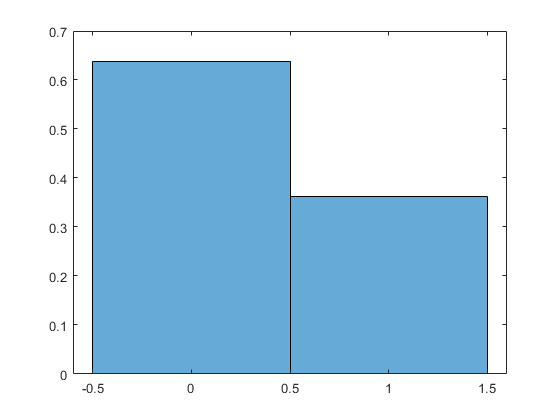

%% OFD: Seminar Week 3
% MATLAB excercises
% 
% Jaroslav Tabacek, 2017

%% Bayesian formula (Unfair coin example)

close all

% Number of measurements
n = 1600;
% Real theta
theta = 0.35;
% Define likelihood function
likelihood_p = @(theta,y)((theta.^y) .* ((1-theta).^(1-y)));
% Theta range
theta_range = linspace(0,1,100);
% Prior distribution
prior_p = theta_range*0;
prior_p(theta_range>=0 & theta_range<=1) = 1;

% Generate random experiment outcome
y = double(rand(n,1) > (1 - theta));
figure;
histogram(y,'Normalization','pdf');

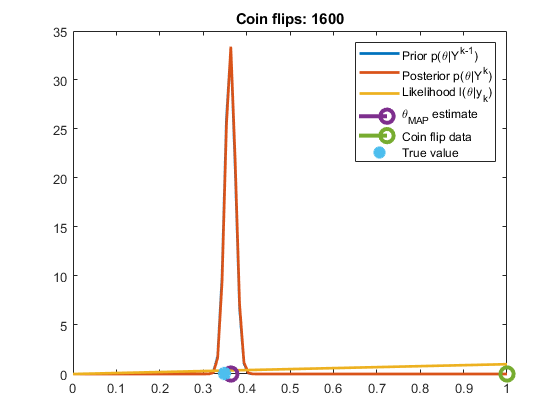


% Plot CPDF change 
plot_values = [1:5,10:10:50,100:100:500,1000];
% plot_values = 1:n;
figure;
for i = 1:n
    % Likelihood for given outcome
    lkh_y = likelihood_p(theta_range,y(i));
    % Calculate posterior
%     posterior_p = lkh_y.*prior_p;
    posterior_p = lkh_y.*prior_p/mean(lkh_y.*prior_p); % normalized
    [~,est_map_id] = max(posterior_p);
    
    if any(plot_values==i) || i == n
    hold off;
    plot(theta_range,prior_p,'linewidth',2,'DisplayName','Prior p(\theta|Y^{k-1})');
    hold on;
    plot(theta_range,posterior_p,'linewidth',2,'DisplayName','Posterior p(\theta|Y^{k})');
    plot(theta_range,lkh_y,'linewidth',2,'DisplayName','Likelihood l(\theta|y_{k})');
    stem(theta_range(est_map_id),0,'Linewidth',3,'Markersize',10,'DisplayName','\theta_{MAP} estimate')
    stem(y(i),0,'Linewidth',3,'Markersize',10,'DisplayName','Coin flip data')
    plot(theta,0,'*', 'Linewidth',3,'Markersize',10,'DisplayName','True value')
    title(['Coin flips: ',num2str(i)])
    legend show
    pause(0.5);
    end
    
    prior_p = posterior_p;
end

### Bayesian estimate of normal distribution

In this section your task will be:

- Generate data from given normal distribution

- Do the marginal estimates of mean and variance using the bayesian method

- To show the probability distribution clearly plot it compared to real values. 

- Change sample size and observe the estimation errors

- Start the whole algorithm with "informed prior" for $\sigma$ that will be extracted from few first samples (take a look at the lecture slides).

- Use different informative priors (different sample size for the initial first samples) with combination of different sample size.

The script below is again prepared for your task. 

More on the theory of bayesian uncertainty estimate for these two particular cases can be found in the lecture slides.

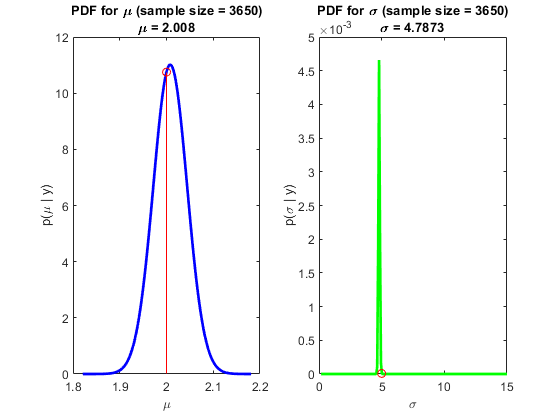

%% Evolution of bayesian mean and variance estimate of normal distribution

% Simulation parameters
N = 3860;   % sample size
SimN = 20;  % number of simulation steps
M = 200;    % number of points in plot

% Generate random sample
mu_real = 2;     % mean
sig_real = 5;   % variance
y = sqrt(sig_real)*randn(N, 1) + mu_real;

%% A priori PDF

% Mean apriori marginal PDF
figure
subplot(1,2,1);
minm = (mu_real-5*sqrt(sig_real));
maxm = (mu_real+5*sqrt(sig_real));
step = (maxm - minm)/M;

mu_ = minm+step:step:maxm;
p_mu = ones(M, 1)./M;     % discrete uniform distribution
plot(mu_, p_mu, 'r', 'Linewidth', 2);
title('A priori pdf for mean estimation \mu');
xlabel('\mu'); ylabel('p( \mu , \sigma | y)')
box on

% Sigma apriori marginal PDF
subplot(1,2,2);
Na = 20;
ya = y(1:Na);
y = y(Na + 1:end);
N = N - Na;
nua = Na - 1;
maxi = 3*sig_real;
mini = 0.1;
stepi = (maxi - mini)/M;
sa = var(ya);

sigma_ = mini+step:stepi:maxi;
p_sigma= chi2pdf(nua*sa^2./(sigma_.^2), nua);             % ~ 1/sigma
plot(sigma_, p_sigma, 'g', 'Linewidth', 2);
title('A priori pdf for variance estimation \sigma');
xlabel('\sigma'); ylabel('p(\sigma | y)')
box on

pause(2);

%% Evolution of mean & variance estimation for increasing data sample size

mu_est = 0;  % mean estimation
for n=2:ceil(N/SimN):N
    
    % sample mean
    mu_est = mean(y(1:n));
    
    % sample variance
%     s2 = 1/(n-1)*sum((y(1:n) - mu_est).^2);
    s2 = var(y(1:n));
    
    % ========== MEAN VALUE ==============
    
    % create sample mu_
    minm = (mu_real-5*sqrt(s2/n));
    maxm = (mu_real+5*sqrt(s2/n));
    step = (maxm - minm)/M;
    mu_ = minm+step:step:maxm;
    
    % Student t distribution for mean estimation (marginal)
    nu = n-1;
    p_mu = sqrt(n/(s2))*tpdf((mu_'-mu_est)/sqrt(s2/n), nu + nua); % sqrt(n/(s2)) is just a scaling factor
%     p_mu = gauss(x, y_est,(s2/n));      % aproximation by normal distribution for nu > 10
    
    % plot mu pdf
    subplot(1,2,1);
    plot(mu_, p_mu, 'b', 'Linewidth', 2);
    hold on;
    % plot real mean and its probability
    stem(mu_real, sqrt(n/(s2))*tpdf((mu_real-mu_est)/sqrt(s2/n), nu + nua), 'r');
    hold off;
    %         axis([(mi-3*sqrt(sig2)) (mi+3*sqrt(sig2)) 0 2]);
    title({['PDF for \mu (sample size = ', num2str(n),')'],...
        ['\mu = ',num2str(mu_est)]});
    xlabel('\mu'); ylabel('p(\mu | y)');
    box on
    
    % ============== VARIANCE =================
    
    % create sample sigma_
    maxi = 3*sig_real;
    mini = 0.1;
    step = (maxi - mini)/M;
    sigma_ = mini+step:step:maxi;
    
    % Variance marginal distribution
    nu = n-1 + Na;
    nus2 = nua*sa^2 + nu*s2^2;
    p_sigma = chi2pdf(nus2./(sigma_.^2), nu);
    
    % plot sigma pdf
    subplot(1,2,2);
    plot(sigma_, p_sigma, 'g', 'Linewidth', 2);
    hold on;
    % plot real sigma and its probability
    stem(sig_real, chi2pdf(nus2./(sig_real.^2), nu), 'r');
    hold off;
    
    %         axis([0 maxi*1.2 0 2]);
    title({['PDF for \sigma (sample size = ', num2str(n),')'],...
        ['\sigma = ',num2str(s2)]});
    xlabel('\sigma'); ylabel('p(\sigma | y)')
    box on
    
    pause(0.5);
    
end

hold off;

### Lead vehicle velocity estimation

Imagine ego vehicle has information only about the position of the ahead of it going lead vehicle (LV). The ACC (adaptive cruise control) needs also LV's velocity for proper functionality. Assume that the unknown LV velocity is constant. So the LV model is rather simple:

$s\left(k+1\right)=s\left(k\right)+v\cdot T_s +e$,

where $v\;\left\lbrack \frac{m}{s}\right\rbrack$ is LV velocity,  $s\;\left\lbrack m\right\rbrack$ is it's distance, $T_s \;\left\lbrack s\right\rbrack$ is sampling time and $e~N\left(0,4\right)$ is measurement noise. Your task will be to:

- implement such model

- make sample measurement

- do the bayesian estimate of constant velocity

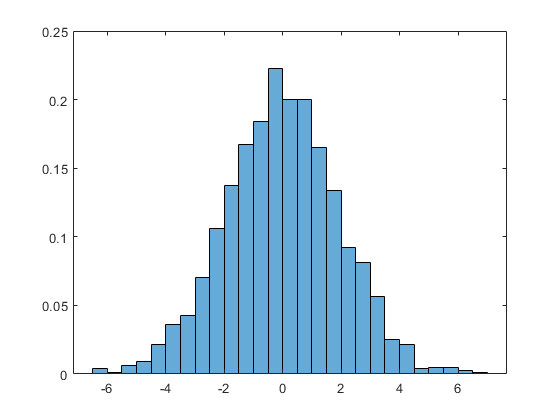

%% OFD: Seminar Week 3
% MATLAB excercises
% 
% David Vošahlík 2020

%% Bayesian formula (LV constant velocity estimation)

close all

% Number of measurements
n = 1600;
% Real LV velocity
LV_velo = 10;       % m/s
Ts = 0.1;           % s
mu = 0;
sig = 2;
% Define likelihood function
likelihood_p = @(velo,distNew, distOld)(gauss(distOld + velo*Ts - distNew, mu, sig));
% Velocity range
v_range = linspace(0,50,100);
% Prior distribution
prior_p = ones(size(v_range));
% Generate random experiment outcome
e = double(sig.*randn(n,1));
figure;
histogram(e,'Normalization','pdf');

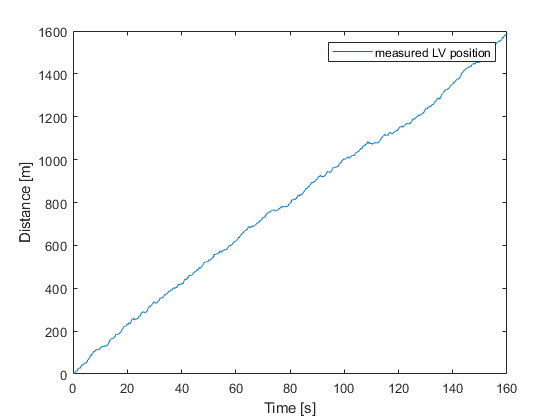


% generate the measurements
s_meas = cumsum(LV_velo*Ts + e);
time = cumsum(Ts*ones(size(s_meas)));

figure;
plot(time, s_meas);
legend('measured LV position');
xlabel('Time [s]');
ylabel('Distance [m]')

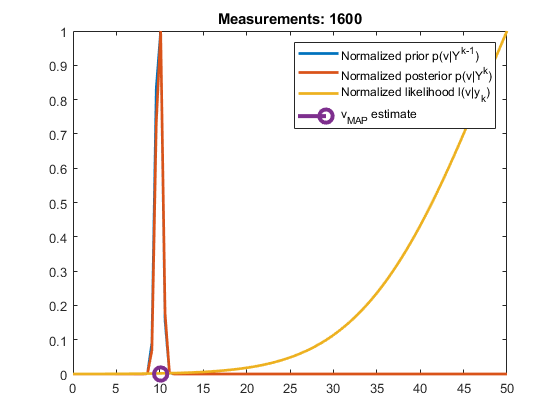


% Plot CPDF change
plot_values = [1:5,10:10:50,100:100:500,1000];
% plot_values = 1:n;
figure;
for i = 2:n
    % Likelihood for given outcome
    lkh_y = likelihood_p(v_range,s_meas(i), s_meas(i - 1));
    % Calculate posterior
    %     posterior_p = lkh_y.*prior_p;
    posterior_p = lkh_y.*prior_p/mean(lkh_y.*prior_p); % normalized
    [~,est_map_id] = max(posterior_p);
    
    if any(plot_values==i) || i == n
        hold off;
        plot(v_range,prior_p/max(prior_p),'linewidth',2,'DisplayName','Normalized prior p(v|Y^{k-1})');
        hold on;
        plot(v_range,posterior_p/max(posterior_p),'linewidth',2,'DisplayName','Normalized posterior p(v|Y^{k})');
        plot(v_range,lkh_y/max(lkh_y),'linewidth',2,'DisplayName','Normalized likelihood l(v|y_{k})');
        stem(v_range(est_map_id),0,'Linewidth',3,'Markersize',10,'DisplayName','v_{MAP} estimate')
        title(['Measurements: ',num2str(i)])
        legend show
        pause(0.5);
    end
    
    prior_p = posterior_p;
end

disp(['Final estimated LV velocity is ' num2str(v_range(est_map_id)) ' m/s']);

Final estimated LV velocity is 10.101 m/s


You can modify the real LV velocity so that it makes step in velocity somewhere and observer the estimate performance.

### Appendix

Here are some handy functions that can be used for your purposes.

function varargout = gauss(x, mi, sig2, plot95, varargin)
%GAUSS Gaussian bell-function. 
% P = GAUSS(x,mi,sig2) calculate probability P of value(s) x in a normal
% distribution defined by mean value mi and variance sig2
%
% GAUSS(x,mi,sig,...) plot gaussian bell-function defined by mean mi and
% variance sig2 and plot a marker at position(s) x (put '[]' for none). Plot options can be
% specified. Example: gauss([-sqrt(2),sqrt(2)],0,2,'Linewidth',2,'Color','b');

% Matisko 2010, Dostal 2013, Hauser 2019

if nargout == 1
    
    % calc probability of point(s) x
    varargout{1} = (sqrt(2*pi*sig2))^(-1) .* exp( -(x - mi).^2 ./ sig2 / 2 );
    
elseif nargout == 0 
    % plot gaussian 
    
    % number of points in graph
    M = 50; 
    sig = sqrt(sig2);
    minm = (mi-4*sig);
    maxm = (mi+4*sig);
    step = (maxm - minm)/M;    
    s = minm+step:step:maxm;        
    gs = gauss(s,mi,sig2);
    gx = gauss(x,mi,sig2);
    
    ishld = ishold;    
    %plot
    if nargin == 4
        
        
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],'Linewidth',2);
        if plot95
            title('Normal PDF with 95% confidence bounds');
        else
            title('Normal PDF with 68% confidence bounds');
        end
        hold on
        plot([mi mi],[max(gs), 0],'DisplayName',['\mu=',num2str(mi)],'Linewidth',1.3);
        if plot95
            plot([mi-2*sig, mi+2*sig],[gauss(mi-2*sig,mi,sig2), gauss(mi+2*sig,mi,sig2)],'DisplayName',['\sigma=',num2str(sig)],'Linewidth',1.3);
        else
            plot([mi-sig, mi+sig],[gauss(mi-sig,mi,sig2), gauss(mi+sig,mi,sig2)],'DisplayName',['\sigma=',num2str(sig)],'Linewidth',1.3);
        end
        
        stem(x,gx,'r');
        
        grid on
        if ~ishld
            hold off
        end       
        
    elseif nargin > 4       
        
        plot(s,gs,'DisplayName',['N(',num2str(mi),',',num2str(sig2),')'],varargin{:}); 
        hold on
        stem(x,gx,'r');   
        
        grid on     
        if ~ishld
            hold off
        end       
        
    else
        error('Wrong number of input parameters. See ''help gauss''');
    end
    legend show
else
    error('Wrong number of output parameters. See ''help gauss''');
end
end
